# GNC Preliminary Calculations & Derivations

Used for intial sizing of spacecraft actuators. More detailed analysis to come as we get better models.

All masses in kilograms (kg), all spacecraft dimensions in meters (m), and all orbital distances/altitudes/parameters in kilometers (km).

clear; close all

## Constants Setup

% Lunar parameters
mu = 4.902800118E03; % kg/m^3 (I forget)
R = 1737.4; % km
gEarth = 9.81 % m/s^2

gEarth = 9.8100


% TODO perturbations on attitude from SRP, etc

## Orbit Parameters

% periapsis and apoapsis
circularLow.peri  = 18; circularLow.apo = 18; % km
circularHigh.peri  = 90; circularHigh.apo = 90; % km
elliptical.peri = 18; elliptical.apo = 90; % km

% stationkeeping (seconds)
circularLow.stationkeepingCadence = 12*3600; % s
circularHigh.stationkeepingCadence = 59*24*3600; % s
elliptical.stationkeepingCadence = NaN; % s

## Components

### Spacecraft

Rough Layout/coordinate frames:

## 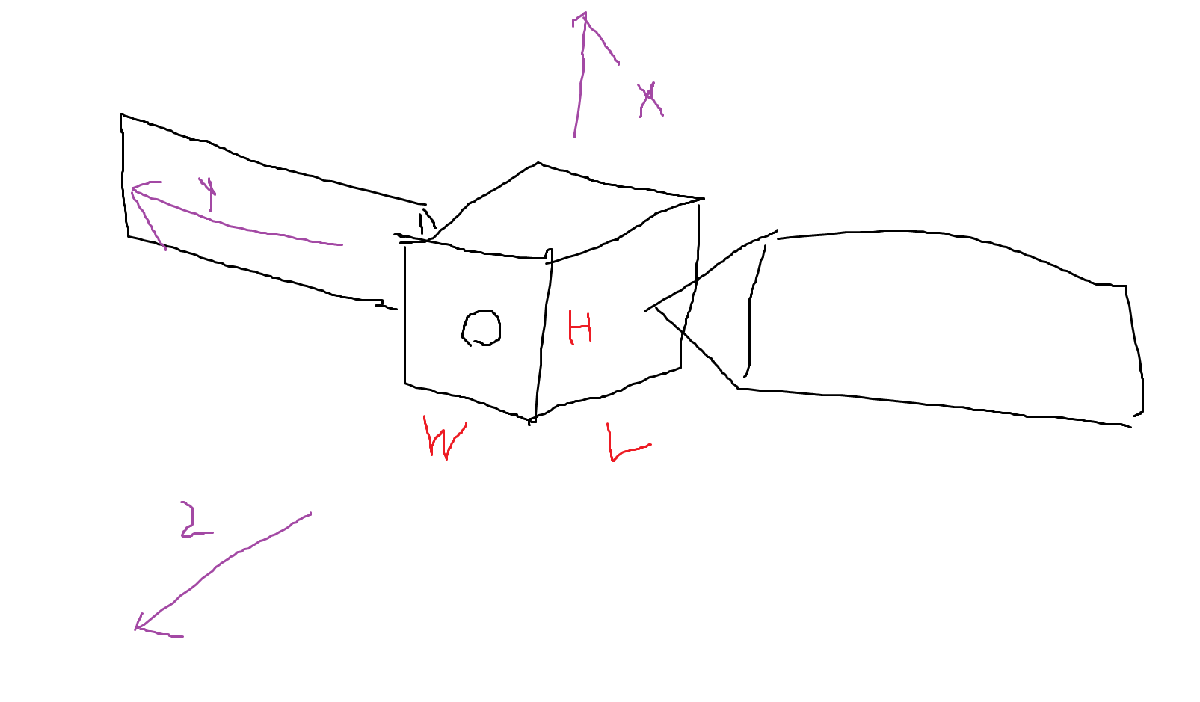

% spacecraft parameters
spacecraftMass = 700; % kg, max mass
% spacecraftMass = 635; % kg, current WET mass

% bus (dim from sun, march 15 msg from conan in sam channel)
bus.dim.x_M = .0845; % m
bus.dim.y_M = .1; % m
bus.dim.z_M = .135; % m

% solar arrays
solar.mass = 6.485584158/2; % kg, from Ben. This is total solar panel mass split in half
% solarPanelArea = 2.06; % m^2, no longer used

solar.dim.x_M = 1.7; % m, from discussion with Ben Slama, EPS lead
solar.dim.z_M = 2.5/100; % 2.5 cm -> m, educated guess
solar.dim.y_M = bus.dim.y_M; % m, height of bus
% solar.dim.x = (solarPanelArea / 2) / solar.dim.y; % m

solar.offsetInX_M = 5/100; % 5 cm -> m, educated guess
solar.axisXLocation_M = [bus.dim.y_M/2, bus.dim.z_M/2]; % location in mechanical y-z plane

% bus pt 2
bus.mass = spacecraftMass - 2*solar.mass;

### Instrument Setup

NFOV.pixelPitch = 6.4; % micro m
NFOV.focalLength = 1.3; % m
NFOV.pixels = [5120, 3840]; % width, height

#### Thrusters

RCSthruster.force = convforce(5, 'lbf', 'N')

RCSthruster = struct with fields:
    force: 22.2411



engineMain.force = convforce(100, 'lbf', 'N')

engineMain = struct with fields:
    force: 444.8222


## Attitude Parameters

### Attitude Parameter (CG, MoI, etc) Derivations

Center of Mass Computation

bus.cg.x_M = bus.dim.x_M/2; bus.cg.y_M = bus.dim.y_M/2; bus.cg.z_M = bus.dim.z_M/2;
solar.cg.x_M = solar.dim.x_M/2; solar.cg.y_M = solar.dim.y_M/2; solar.cg.z_M = solar.dim.z_M/2;

Moments of Inertia (MOI)

Assume evenly distributed mass across rectangular prism spacecraft and solar panels. Solar panels are assumed to be facing in body axis Z direciton. Later will want ability to do it when rotated as wel to body axis X direction. As a reminder:

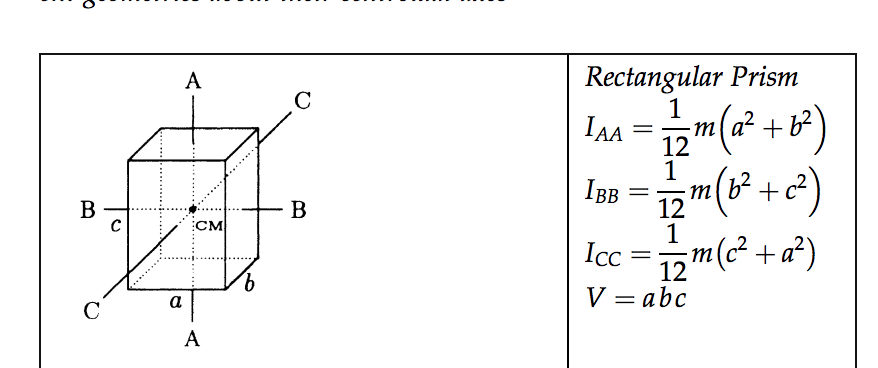

% bus
bus.MoI.x_B = 1/12*bus.mass*(bus.dim.x_M^2 + bus.dim.z_M^2);
bus.MoI.y_B = 1/12*bus.mass*(bus.dim.y_M^2 + bus.dim.z_M^2);
bus.MoI.z_B = 1/12*bus.mass*(bus.dim.x_M^2 + bus.dim.y_M^2);

% solar panel
solar.MoI.x_B = 1/12*solar.mass*(solar.dim.x_M^2 + solar.dim.z_M^2);
solar.MoI.y_B = 1/12*solar.mass*(solar.dim.y_M^2 + solar.dim.z_M^2);
solar.MoI.z_B = 1/12*solar.mass*(solar.dim.x_M^2 + solar.dim.y_M^2);

Combine into spacecraft

sc = spacecraftProperties(bus, solar);

## Orbit Requirements

### Uncertainty Growth

TODO stm on initial covariance

### Accelerometer Math

#### Derivations

RCS thrusters

numFiringIn1Dir = 3;
accelMax = 1.2 * numFiringIn1Dir * RCSthruster.force / sc.mass % m/s^2

accelMax = 0.1144

fprintf("RCS max acceleration is about %f g's", accelMax/gEarth)

RCS max acceleration is about 0.011660 g's

Main Engine

accelMax = 1.2 * engineMain.force / sc.mass % m/s^2

accelMax = 0.7626

fprintf("Main engine max acceleration is about %f g's", accelMax/gEarth)

Main engine max acceleration is about 0.077732 g's

## Attitude Requirements

### Slew Requirements

180 flip about imaging axis in 30 minutes, NO PERTURBATIONS INCLUDED

dt = 30*60 /2 

dt = 900

torqueMax = 1.2 * (4/dt^2 * sc.MoI.z_B * deg2rad(180)) % Nm

torqueMax = 1.5502e-04

fprintf("max torque in mNm: %f", torqueMax*1e3)

max torque in mNm: 0.155024

### Desaturation Requirements TODO

18x18 km orbit, aka circular low

% circularLow.momentumBuildUp = PERTURB*circularLow.stationkeepingCadence

18x90 km orbit, aka elliptical

90x90 km orbit, aka circular high

### INSTR Math

#### Derivations

Deriving instrument parameters

NFOV.angularResolution = NFOV.pixelPitch*1E-6/NFOV.focalLength; % radians
NFOV.fov.width = NFOV.angularResolution*NFOV.pixels(1);
NFOV.fov.height = NFOV.angularResolution*NFOV.pixels(2);

rad2deg(NFOV.angularResolution)

ans = 2.8207e-04

rad2deg(NFOV.fov.width)

ans = 1.4442

rad2deg(NFOV.fov.height)

ans = 1.0832

Deriving imaging parameters at various altitudes

% error = 3*deg2rad(.01); 
error = 3*deg2rad(60/3600); % 3 sigma of 60 arc seconds

High resolution imaging, at the low orbit of <20 km

img.height = 2*elliptical.peri*tan(NFOV.fov.height/2); % km
img.width  = 2*elliptical.peri*tan(NFOV.fov.width/2) % km

img = struct with fields:
    height: 0.3403
     width: 0.4537


delta = elliptical.peri*tan(error) % km

delta = 0.0157

pcntShift.height = (delta)/img.height;
pcntShift.width  = delta/img.width

pcntShift = struct with fields:
    height: 0.0462
     width: 0.0346



% TODO: incorporate movement
% TODO: determine if we're doing height along orbit or width along orbit

Low resolution imaging, at the high orbit of <100 km

img.height = 2*elliptical.apo*tan(NFOV.fov.height/2); % km
img.width  = 2*elliptical.apo*tan(NFOV.fov.width/2) % km

img = struct with fields:
    height: 1.7015
     width: 2.2687


delta = elliptical.apo*tan(error) % km

delta = 0.0785

pcntShift.height = delta/img.height;
pcntShift.width  = delta/img.width

pcntShift = struct with fields:
    height: 0.0462
     width: 0.0346



% TODO: incorporate movementx